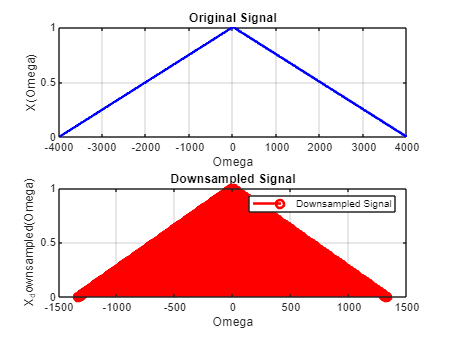

% Given parameters
Omega_N = 4000;  % Maximum frequency in Hz
M = 3;           % Downsampling factor

% Calculate sampling period
Ts = 1 / Omega_N;

% Define the range of Omega
Omega = linspace(-Omega_N, Omega_N, 1000);

% Define the original signal X(Ω) as a triangular pulse
X_Omega = zeros(size(Omega));
X_Omega(Omega >= -Omega_N & Omega <= 0) = (Omega(Omega >= -Omega_N & Omega <= 0) + Omega_N) / Omega_N;
X_Omega(Omega > 0 & Omega <= Omega_N) = (Omega_N - Omega(Omega > 0 & Omega <= Omega_N)) / Omega_N;

% Perform downsampling
X_downsampled = downsample(X_Omega, M);
Omega_downsampled = downsample(Omega, M)/3;

% Plot the original and downsampled signals
figure;
subplot(2, 1, 1);
plot(Omega, X_Omega, 'b', 'LineWidth', 2);
title('Original Signal');
xlabel('Omega');
ylabel('X(Omega)');
grid on;

subplot(2, 1, 2);
stem(Omega_downsampled, X_downsampled, 'r', 'LineWidth', 2);
title('Downsampled Signal');
xlabel('Omega');
ylabel('X_downsampled(Omega)');
grid on;

legend('Downsampled Signal');